# Kersbergen et al. 2022

% Figure 3 - histology and ABRs


## Inner hair cells, outer hair cells

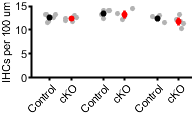


addpath('F:\Calvin\tmem16a\immunostaining\whole mount myo7a P14\quantification')
conIHCapex = [11.63637976,11.70372847,13.21416559,12.52433706,13.23455136,13.22410849];
conIHCmid = [13.13490115,13.98861073,12.37668013,13.96738079,13.99747128];
conIHCbase = [11.56450391,12.73164521,13.042321];

ckoIHCapex = [12.93233515,12.46922566,12.52170429,11.9665133,11.71381716];
ckoIHCmid = [12.18457896,12.85729592,14.48880595,13.45225465];
ckoIHCbase = [13.14302972,10.36591687,12.18489711,11.75380062,11.42187729];

conOHCapex = [41.83555579,40.12706905,44.44764788,39.28087534,44.8354189,45.81209014];
conOHCmid = [40.54686875,44.25487757,42.63078713,43.24515977,47.04068216];
conOHCbase = [37.29552512,37.91201019,39.39313282];

ckoOHCapex = [40.80870202,39.43755093,42.01727439,43.47019117,37.99848006];
ckoOHCmid = [39.74493615,44.2862415,42.30731337,41.62584457];
ckoOHCbase = [40.26800595,35.12894049,35.97445813,36.32992918,35.72997511];

ylbl = ('IHCs per 100 um');
ylbl2 = ('OHCs per 100 um');
dim = [2 1.2];
conditions = {'Control','cKO','Control','cKO','Control','cKO'};
compare6(conIHCapex,ckoIHCapex,conIHCmid,ckoIHCmid,conIHCbase,ckoIHCbase,conditions,ylbl,dim);
ylim([0 15])

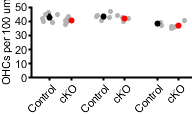


figure
compare6(conOHCapex,ckoOHCapex,conOHCmid,ckoOHCmid,conOHCbase,ckoOHCbase,conditions,ylbl2,dim);
ylim([0 50])
yticks([0 10 20 30 40 50])


geno = {'con','con','con','con','con','con','con','con','con','con','con','con','con','con','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'}';
mouse = [1 2 3 4 5 6 2 3 4 5 6 2 5 6 7 8 9 10 11 7 9 10 11 7 8 9 10 11]';
location = {'apex','apex','apex','apex','apex','apex','middle','middle','middle','middle','middle','base','base','base','apex','apex','apex','apex','apex','middle','middle','middle','middle','base','base','base','base','base'}'; 
IHCs = [conIHCapex(1),conIHCapex(2),conIHCapex(3),conIHCapex(4),conIHCapex(5),conIHCapex(6),conIHCmid(1),conIHCmid(2),conIHCmid(3),conIHCmid(4),conIHCmid(5),conIHCbase(1),conIHCbase(2),conIHCbase(3),ckoIHCapex(1),ckoIHCapex(2),ckoIHCapex(3),ckoIHCapex(4),ckoIHCapex(5),ckoIHCmid(1),ckoIHCmid(2),ckoIHCmid(3),ckoIHCmid(4),ckoIHCbase(1),ckoIHCbase(2),ckoIHCbase(3),ckoIHCbase(4),ckoIHCbase(5)]';

tbl = table(geno,mouse,location,IHCs,'VariableNames',{'Genotype','Mouse','Location','IHCs'})

tbl = 28×4 table
    Genotype    Mouse     Location      IHCs 
    ________    _____    __________    ______

    {'con'}       1      {'apex'  }    11.636
    {'con'}       2      {'apex'  }    11.704
    {'con'}       3      {'apex'  }    13.214
    {'con'}       4      {'apex'  }    12.524
    {'con'}       5      {'apex'  }    13.235
    {'con'}       6      {'apex'  }    13.224
    {'con'}       2      {'middle'}    13.135
    {'con'}       3      {'middle'}    13.989
    {'con'}       4      {'middle'}    12.377
    {'con'}       5      {'middle'}    13.967
    {'con'}       6      {'middle'}    13.997
    {'con'}       2      {'base'  }    11.565
    {'con'}       5      {'base'  }    12.732
    {'con'}       6      {'base'  }    13.042
    {'cko'}       7      {'apex'  }    12.932
    {'cko'}       8      {'apex'  }    12.469


lme = fitlme(tbl,'IHCs~Genotype+(1|Location)+(1|Mouse)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations              28
    Fixed effects coefficients           2
    Random effects coefficients         14
    Covariance parameters                3

Formula:
    IHCs ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    78.252    84.913    -34.126          68.252  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF    pValue        Lower      Upper  
    {'(Intercept)' }          12.807    0.35791     35.783    26    1.2021e-23     12.071     13.543
    {'Genotype_cko'}        -0.38913      0.323    -1.2047    26       0.23917    -1.0531    0.27482

Random effects covariance parameters (95% CIs):
Group: Location (3 Levels)
    Name1                  Name2                  Type   


OHCs =  [conOHCapex(1),conOHCapex(2),conOHCapex(3),conOHCapex(4),conOHCapex(5),conOHCapex(6),conOHCmid(1),conOHCmid(2),conOHCmid(3),conOHCmid(4),conOHCmid(5),conOHCbase(1),conOHCbase(2),conOHCbase(3),ckoOHCapex(1),ckoOHCapex(2),ckoOHCapex(3),ckoOHCapex(4),ckoOHCapex(5),ckoOHCmid(1),ckoOHCmid(2),ckoOHCmid(3),ckoOHCmid(4),ckoOHCbase(1),ckoOHCbase(2),ckoOHCbase(3),ckoOHCbase(4),ckoOHCbase(5)]';
tbl = table(geno,mouse,location,OHCs,'VariableNames',{'Genotype','Mouse','Location','OHCs'})

tbl = 28×4 table
    Genotype    Mouse     Location      OHCs 
    ________    _____    __________    ______

    {'con'}       1      {'apex'  }    41.836
    {'con'}       2      {'apex'  }    40.127
    {'con'}       3      {'apex'  }    44.448
    {'con'}       4      {'apex'  }    39.281
    {'con'}       5      {'apex'  }    44.835
    {'con'}       6      {'apex'  }    45.812
    {'con'}       2      {'middle'}    40.547
    {'con'}       3      {'middle'}    44.255
    {'con'}       4      {'middle'}    42.631
    {'con'}       5      {'middle'}    43.245
    {'con'}       6      {'middle'}    47.041
    {'con'}       2      {'base'  }    37.296
    {'con'}       5      {'base'  }    37.912
    {'con'}       6      {'base'  }    39.393
    {'cko'}       7      {'apex'  }    40.809
    {'cko'}       8      {'apex'  }    39.438


lme = fitlme(tbl,'OHCs~Genotype+(1|Location)+(1|Mouse)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations              28
    Fixed effects coefficients           2
    Random effects coefficients         14
    Covariance parameters                3

Formula:
    OHCs ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    135.23    141.89    -62.617          125.23  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF    pValue        Lower      Upper  
    {'(Intercept)' }         41.485      1.4597      28.42    26    4.1497e-21     38.484     44.485
    {'Genotype_cko'}        -1.7484     0.97337    -1.7963    26       0.08408    -3.7492    0.25235

Random effects covariance parameters (95% CIs):
Group: Location (3 Levels)
    Name1                  Name2                  Type   

## spiral ganglion neurons

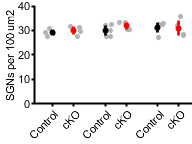


addpath('F:\Calvin\tmem16a\immunostaining\x sec myo7a tuj1\P14 SGNs\quantification')
conapex = [27.68007266,29.1935893,28.94658244,30.88393032];
conmid = [27.66784576,27.50207164,29.88700513,32.58402825,32.16730678];
conbase = [32.46487022,27.32916505,30.61386581,32.7811685,32.58307785];

ckoapex = [31.235137,29.70402065,31.80140748,27.46062588];
ckomid = [30.38268041,30.51444293,33.3890469,33.14870393];
ckobase = [28.08180706,31.96315532,35.68986541,28.19712963];

ylbl = ('SGNs per 100 um2');
dim = [2 1.5];
conditions = {'Control','cKO','Control','cKO','Control','cKO'};
compare6(conapex,ckoapex,conmid,ckomid,conbase,ckobase,conditions,ylbl,dim);
ylim([0 40])

geno = {'con','con','con','con','con','con','con','con','con','con','con','con','con','con','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'}';
mouse = [1 1 1 2 2 2 3 3 3 4 4 4 5 5 6 6 6 7 7 7 8 8 8 9 9 9]';
location = {'apex','middle','base','apex','middle','base','apex','middle','base','apex','middle','base','middle','base','apex','middle','base','apex','middle','base','apex','middle','base','apex','middle','base'}'; 
SGNs = [conapex(1),conmid(1),conbase(1),conapex(2),conmid(2),conbase(2),conapex(3),conmid(3),conbase(3),conapex(4),conmid(4),conbase(4),conmid(5),conbase(5),ckoapex(1),ckomid(1),ckobase(1),ckoapex(2),ckomid(2),ckobase(2),ckoapex(3),ckomid(3),ckobase(3),ckoapex(4),ckomid(4),ckobase(4)]';


tbl = table(geno,mouse,location,SGNs,'VariableNames',{'Genotype','Mouse','Location','SGNs'})

tbl = 26×4 table
    Genotype    Mouse     Location      SGNs 
    ________    _____    __________    ______

    {'con'}       1      {'apex'  }     27.68
    {'con'}       1      {'middle'}    27.668
    {'con'}       1      {'base'  }    32.465
    {'con'}       2      {'apex'  }    29.194
    {'con'}       2      {'middle'}    27.502
    {'con'}       2      {'base'  }    27.329
    {'con'}       3      {'apex'  }    28.947
    {'con'}       3      {'middle'}    29.887
    {'con'}       3      {'base'  }    30.614
    {'con'}       4      {'apex'  }    30.884
    {'con'}       4      {'middle'}    32.584
    {'con'}       4      {'base'  }    32.781
    {'con'}       5      {'middle'}    32.167
    {'con'}       5      {'base'  }    32.583
    {'cko'}       6      {'apex'  }    31.235
    {'cko'}       6      {'middle'}    30.383



lme = fitlme(tbl,'SGNs~Genotype+(1|Location)+(1|Mouse)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations              26
    Fixed effects coefficients           2
    Random effects coefficients         12
    Covariance parameters                3

Formula:
    SGNs ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    122.26    128.55    -56.128          112.26  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF    pValue        Lower      Upper 
    {'(Intercept)' }         30.231      0.738     40.963    24    1.0027e-23     28.708    31.754
    {'Genotype_cko'}        0.73321     1.0853    0.67556    24       0.50578    -1.5068    2.9732

Random effects covariance parameters (95% CIs):
Group: Location (3 Levels)
    Name1                  Name2                  Type         